clc
clear all
%Assumed machine operated condition
gammaRated = pi/12;
IsRated = 6.5;
RsRated = 0.77;
LdRated = 2.7e-3;
LqRated = 4.7e-3;
IqRated = IsRated * cos(gammaRated);
IdRated = -IsRated * sin(gammaRated);
weRated = 600*5/60*2*pi;
PsiDM = 0.055;
EexRated = weRated * PsiDM + (LdRated - LqRated) * (weRated * IdRated)

EexRated =   18.335794808658029


3/2*5*(PsiDM*IqRated + (LdRated - LqRated) * IdRated)

ans =    2.615123478635060



[1.1;4.5e-3;]*(0.5:0.25:1.5)

ans =    0.550000000000000   0.825000000000000   1.100000000000000   1.375000000000000   1.650000000000000
   0.002250000000000   0.003375000000000   0.004500000000000   0.005625000000000   0.006750000000000


RsN = 0.528*(0.5:0.25:1.5);
NDD = 1./(3.4e-3*(0.5:0.25:1.5));
NQQ = 1./(4.5e-3*(0.5:0.25:1.5));
Psi = 0.053 *(0.5:0.25:1.5);
[RsN',NDD',NQQ',Psi'];

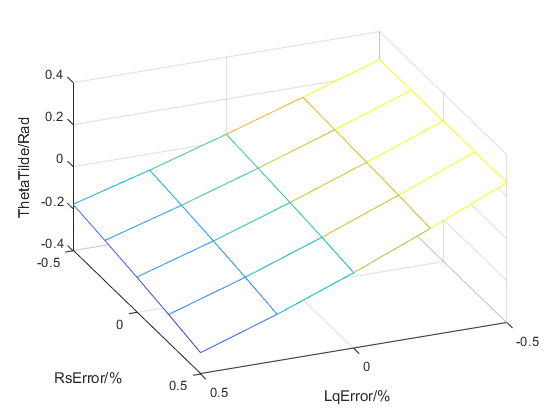

%Plot the relationship between the error of resistance, induc4tance and
%sensorless observer results. 
%Two special operating point for all model-based sensorless control

%1.gamma=0, the position observation error is insensitive to resistance
%mismatch and the amplitude of extended EMF is insensitive to q-axis inductance mismatch.

%1.gamma=pi/2, the position observation error is insensitive to q-axis inductance
%mismatch and the amplitude of extended EMF is insensitive to resistance mismatch.

RsError = [-0.5:0.25:0.5] .* RsRated;
LqError = [-0.5:0.25:0.5] .* LqRated;
EexError = zeros(5,5);
ThetaError = zeros(5,5);
for i = 1:5
    for j = 1:5
        TempA = EexRated * cos(gammaRated) - RsError(i) * IsRated;
        TempB = EexRated * sin(gammaRated) + weRated * LqError(j) * IsRated;
        EexError(i,j) = sqrt(TempA^2 + TempB^2);
        ThetaError(i,j) = -atan2(TempB,TempA) + gammaRated;
        if(ThetaError(i,j) + gammaRated > pi/2 || ThetaError(i,j) + gammaRated < -pi/2)
            EexError(i,j) = - EexError(i,j);
        end
    end
end
figure()
% subplot(1,2,1)
mesh(RsError/RsRated,LqError/LqRated,ThetaError);
ylabel("RsError/%");
xlabel("LqError/%");
zlabel("ThetaTilde/Rad");
view([-130 45])

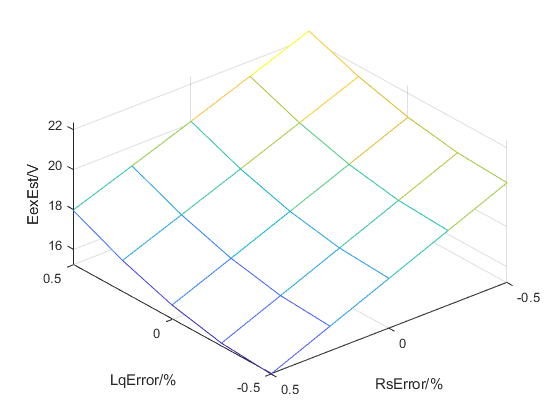

figure()
% subplot(1,2,2)
mesh(RsError/RsRated,LqError/LqRated,EexError);
ylabel("RsError/%");
xlabel("LqError/%");
zlabel("EexEst/V");
view([-130 45])

% Define the three parameters
RsErrorScatter = [-0.5:0.25:0.5] .* RsRated;  % Parameter 1 values
LqErrorScatter = [-0.5:0.25:0.5] .* LqRated;  % Parameter 2 values
GammaScatter = 0:pi/4/4:pi/4;  % Parameter 3 values

% % Create a meshgrid for the three parameters
[Param1Grid, Param2Grid, Param3Grid] = meshgrid(RsErrorScatter, LqErrorScatter, GammaScatter);
% 
% Calculate the variable influenced by the parameters
ThetaError3 = zeros(5,5,5);
EexError3 = zeros(5,5,5);
for i = 1:5
    for j = 1:5
        for k = 1:5
            TempA = EexRated * cos(Param3Grid(i,j,k)) - Param1Grid(i,j,k) * IsRated;
            TempB = EexRated * sin(Param3Grid(i,j,k)) + weRated * Param2Grid(i,j,k) * IsRated;
            EexError3(i,j,k) = sqrt(TempA^2 + TempB^2);
            ThetaError3(i,j,k) = atan2(TempB,TempA) - Param3Grid(i,j,k);
            if(ThetaError3(i,j,k) + Param3Grid(i,j,k) > pi/2 ||ThetaError3(i,j,k) + Param3Grid(i,j,k) < -pi/2)
                EexError3(i,j,k) = - EexError3(i,j,k);
            end
        end
    end
end

% Define the three parameters
RsErrorScatter = [-0.5:0.25:0.5] .* RsRated;  % Parameter 1 values
LqErrorScatter = [-0.5:0.25:0.5] .* LqRated;  % Parameter 2 values
GammaScatter = 0:pi/4/4:pi/4;  % Parameter 3 values

% Create a meshgrid for the three parameters
[Param1Grid, Param2Grid, Param3Grid] = meshgrid(RsErrorScatter, LqErrorScatter, GammaScatter);

% Calculate the variable influenced by the parameters
ThetaError3 = zeros(5, 5, 5);
EexError3 = zeros(5, 5, 5);
for i = 1:5
    for j = 1:5
        for k = 1:5
            TempA = EexRated * cos(Param3Grid(i,j,k)) - Param1Grid(i,j,k) * IsRated;
            TempB = EexRated * sin(Param3Grid(i,j,k)) + weRated * Param2Grid(i,j,k) * IsRated;
            EexError3(i,j,k) = sqrt(TempA^2 + TempB^2);
            ThetaError3(i,j,k) = atan2(TempB, TempA) - Param3Grid(i,j,k);
            if (ThetaError3(i,j,k) + Param3Grid(i,j,k) > pi/2 || ThetaError3(i,j,k) + Param3Grid(i,j,k) < -pi/2)
                EexError3(i,j,k) = -EexError3(i,j,k);
            end
        end
    end
end

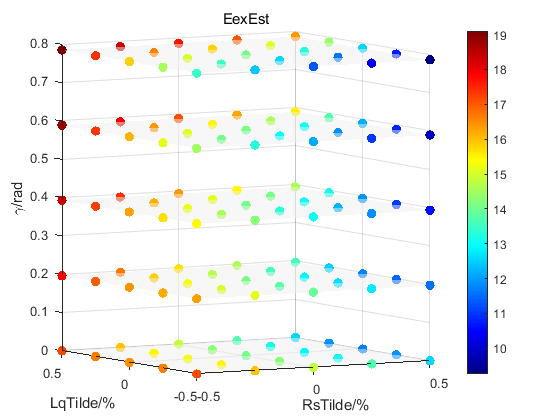

% Create a 3D scatter plot with color mapping for EexError3
figure;
scatter3(Param1Grid(:)/RsRated, Param2Grid(:)/LqRated, Param3Grid(:), 50, EexError3(:),'filled');
colorbar;
caxis([min(EexError3(:)), max(EexError3(:))]); % Set color limits
colormap("jet")
hold on
for i = 1:5
    surf([-0.5 0.5],[-0.5,0.5],ones(2,2)*GammaScatter(i),'FaceAlpha', 0.5, 'EdgeColor', 'none',...
        "FaceColor", [0.94,0.94,0.94])
end
hold off
view([-30 5]);

ylabel('LqTilde/%');
xlabel('RsTilde/%');
zlabel('{\gamma}/rad');
title('EexEst');

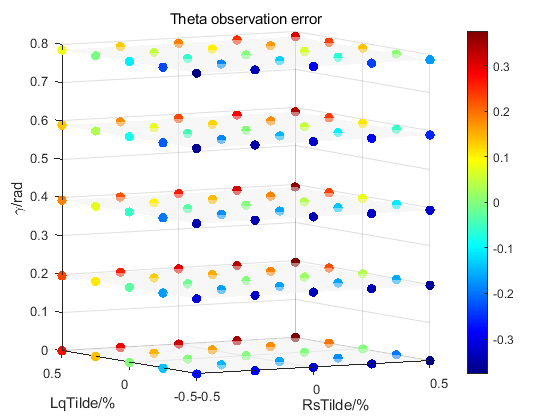


% Create a 3D scatter plot with color mapping for ThetaError3
figure;
scatter3(Param1Grid(:)/RsRated, Param2Grid(:)/LqRated, Param3Grid(:), 50, ThetaError3(:),'filled');
colorbar;
caxis([min(ThetaError3(:)), max(ThetaError3(:))]); % Set color limits
colormap("jet")
hold on
for i = 1:5
    surf([-0.5 0.5],[-0.5,0.5],ones(2,2)*GammaScatter(i),'FaceAlpha', 0.5, 'EdgeColor', 'none',...
        "FaceColor", [0.94,0.94,0.94])
end
hold off
view([-30 5]);

ylabel('LqTilde/%');
xlabel('RsTilde/%');
zlabel('{\gamma}/rad');
title('Theta observation error');